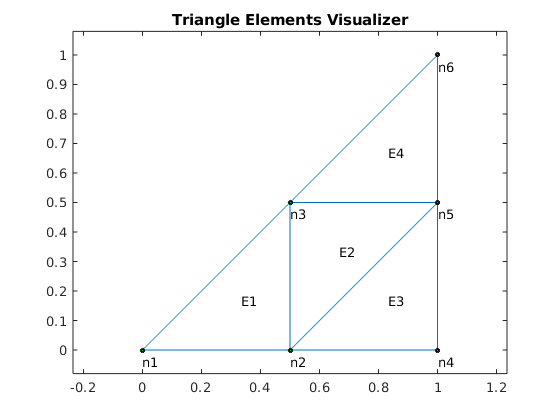

clearvars
close all

a11 = 1.0;
a12 = 0.0;
a21 = a12;
a22 = a11;
a00 = 0.0;
f = 1.0;

nodes=[
    0.0, 0.0;
    0.5, 0.0;
    0.5, 0.5;
    1.0, 0.0;
    1.0, 0.5;
    1.0, 1.0
    ];

elem = [
    1, 2, 3;
    5, 3, 2;
    2, 4, 5;
    3, 5, 6
    ];

numNodes = size(nodes,1);
numElem = size(elem,1);

numbering=1;

plotElements(nodes,elem,numbering);


K=zeros(numNodes);
F=zeros(numNodes,1);
coeff=[a11,a12,a21,a22,a00,f];

for e = 1:numElem
    [Ke,Fe] = linearTriangElemShort(coeff,nodes,elem,e);
    rows=[elem(e,1),elem(e,2),elem(e,3)];
    cols=rows;
    K(rows,cols) = K(rows,cols) + Ke;
    if coeff(6) ~= 0
        F(rows,1) = F(rows,1) + Fe;
    end
end

%B.C.
fixedNodes=[4,5,6];
freeNodes=setdiff(1:numNodes,fixedNodes);

%Essential B.C.
u = zeros(numNodes,1);
u(fixedNodes) = 0.0;

%Natural B.C.:
Q=zeros(numNodes,1);
Q(freeNodes) = 0.0; %all of them are zero

%Reduced system
Im = F(freeNodes) + Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

%Solve the reduced system
um = Km\Im;
u(freeNodes) = um;

format short e
u

u =    3.1250e-01
   2.2917e-01
   1.7708e-01
            0
            0
            0



%PostProcess: compute secondary varibles, table and contour plot
%Secondary variables
Q = K*u-F

Q =   -6.9389e-18
   1.1102e-16
            0
  -1.5625e-01
  -3.0208e-01
  -4.1667e-02


%Table: create an structure
Table.NodeNum=(int32(1:numNodes))';
Table.X=nodes(:,1);
Table.Y=nodes(:,2);
Table.U=u;
Table.Q=Q;
struct2table(Table)

ans = 6×5 table
    NodeNum        X             Y             U              Q     
    _______    __________    __________    __________    ___________

       1       0.0000e+00    0.0000e+00    3.1250e-01    -6.9389e-18
       2       5.0000e-01    0.0000e+00    2.2917e-01     1.1102e-16
       3       5.0000e-01    5.0000e-01    1.7708e-01     0.0000e+00
       4       1.0000e+00    0.0000e+00    0.0000e+00    -1.5625e-01
       5       1.0000e+00    5.0000e-01    0.0000e+00    -3.0208e-01
       6       1.0000e+00    1.0000e+00    0.0000e+00    -4.1667e-02


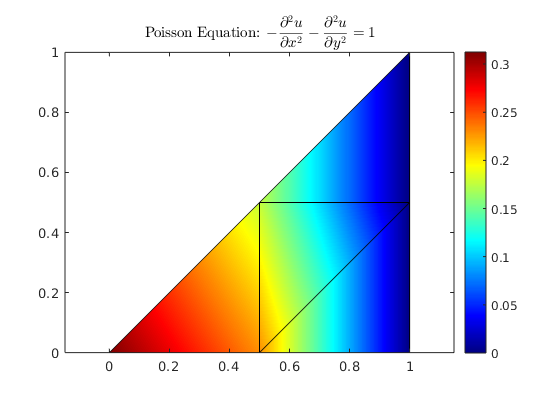


title = ['Poisson Equation: ', ...
         '$$-\frac{\partial^{2} u}{\partial x^{2}}-',...];
         '\frac{\partial^{2} u}{\partial y^{2}} = 1$$'];
colorScale = 'jet'; 
plotContourSolutionLT(nodes,elem,u,title,colorScale)